clear all;
close all;
clc;

markersize = 20;
linewidth = 2;

## Download the data

This dataset, provided by John Hopkins University, is updated every day for all countries. We download the CSV dataset.

url = 'https://raw.githubusercontent.com/CSSEGISandData/COVID-19/master/csse_covid_19_data/csse_covid_19_time_series/time_series_19-covid-Confirmed.csv';
fn = 'time_series_19-covid-Confirmed.csv';
websave(fn, url);

## List all available countries

countries = getcountries();
countries

countries = 152×1 cell array
    {'Afghanistan'             }
    {'Albania'                 }
    {'Algeria'                 }
    {'Andorra'                 }
    {'Antigua and Barbuda'     }
    {'Argentina'               }
    {'Armenia'                 }
    {'Australia'               }
    {'Austria'                 }
    {'Azerbaijan'              }
    {'Bahrain'                 }
    {'Bangladesh'              }
    {'Barbados'                }
    {'Belarus'                 }
    {'Belgium'                 }
    {'Benin'                   }
    {'Bhutan'                  }
    {'Bolivia'                 }
    {'Bosnia and Herzegovina'  }
    {'Brazil'                  }
    {'Brunei'                  }
    {'Bulgaria'                }
    {'Burkina Faso'            }
    {'Cambodia'                }
    {'Cameroon'                }
    {'Canada'                  }
    {'Central African Republic'}
    {'Chile'                   }
    {'China'                   }
    {'Colombia

## Get the zones

Some countries may have multiple zones (or states), so let's find out what zones we have. First change country to the country you want to investigate.

country = 'Netherlands'; % country for which we want to fit
zones = getzones('Netherlands') % what zones are there?

zones = 1×3 cell array
    {'Netherlands'}    {'Curacao'}    {'Aruba'}


## Get the data

Put the correct zone in the variable zone below, and we get the data for march.

zone = 'Netherlands';

y = getinfections(country, zone);
offset = 40; % start plots from march 1
y = y(offset:end); % only march
t = 1:length(y); % time in days from March

## Make figure with data

Lets make an initial plot of the data.

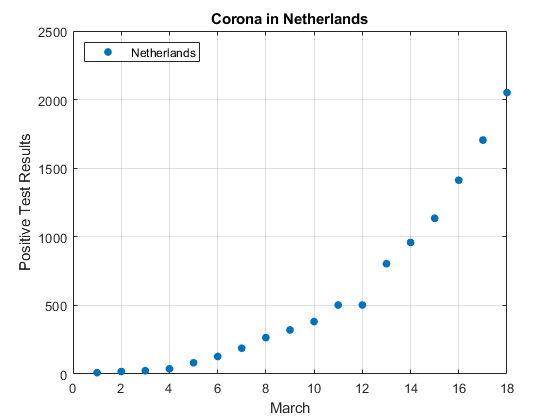

figure;
plot(t,y,'.','MarkerSize',markersize,'DisplayName',country);
hold on;

grid on
title(sprintf('Corona in %s',country))
xlabel('March')
ylabel('Positive Test Results')
legend('Location','NorthWest');

## Compute exponential fit using least squares

To compute an initial fit, we transform the y-data to log scale, and then do a least squares fit. This essentially gives us an exponential fit, but it may not be very good, because the squared errors are computed in log scale. This means that, for example, that errors over estimation and underestimation are not counted in the same way in the squared error.

skip = 5; % do not fit first 5 days
maxt = 20; % until when to predict

t = t(skip:end);
y = y(skip:end);

X = [t',ones(size(t'))]; % the input variable (time, offset)
Y = log10(y'); % convert to logscale and do fit there

beta = inv(X'*X)*X'*Y; % least square fit

tfar = [(1:maxt)',ones(maxt,1)]; % what dates to predict
ypred_logscale = tfar*beta; % compute predictions in logscale
ypred = 10.^ypred_logscale; % convert back to normal scale

## Figure with least squares fit

Let's display this initial 'simple' fit. 

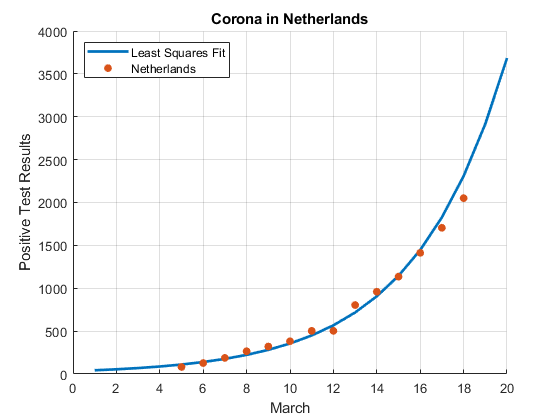

figure;
hold on;
plot(1:maxt,ypred,'DisplayName','Least Squares Fit','LineWidth',linewidth);
plot(t,y,'.','MarkerSize',markersize,'DisplayName',country);

grid on
title(sprintf('Corona in %s',country))
xlabel('March')
ylabel('Positive Test Results')
legend('Location','NorthWest');

## Compute growth factors and display fit information

From the fit we can compute the growth factor. 

$y = C A^t$ is the formula for our model. 

A = 10.^beta(1);
C = 10.^beta(2);
the_function = A.^tfar(:,1) * C; % recompute predictions
% observe that ypred = the_function, thus the formula is indeed correct

## Robust fit using previous one as initialization

If you have the curve fitting toolbox installed, this will fit a better model to the data we have. It is using least squares errors in the original scale.

x = t;
ft = fittype( 'A * C^x', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'iter';
opts.Algorithm = 'Levenberg-Marquardt';

opts.StartPoint = [C A];
% Fit model to data.
[fitresult, gof] = fit(x', y', ft, opts);


                                        First-Order                    Norm of 
 Iteration  Func-count    Residual       optimality      Lambda           step
     0           3          104704        1.09e+07         0.01              0
     1           6         68596.8        9.23e+06        0.001        12.9354
     2           9         25431.5        1.85e+05       0.0001        1.85522
     3          12         25416.1             303        1e-05      0.0529709
     4          15         25416.1            10.9        1e-06     0.00421788
Success, but fitting stopped because change in residuals less than tolerance (TolFun).


## Plot robust fit

Lets plot the robust fit. It looks like a better fit.

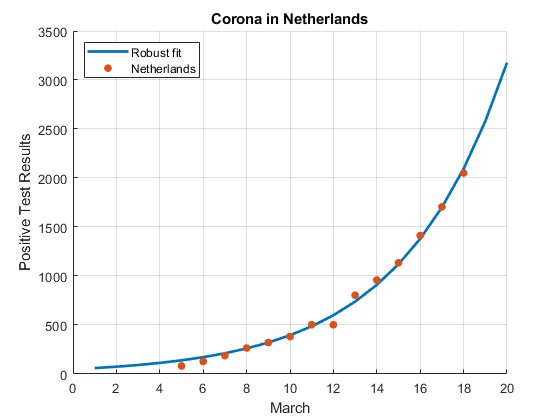

figure;
hold on;
plot(tfar(:,1),feval(fitresult,tfar(:,1)),'DisplayName','Robust fit','LineWidth',linewidth);
plot(t,y,'.','MarkerSize',markersize,'DisplayName',country);

grid on
title(sprintf('Corona in %s',country))
xlabel('March')
ylabel('Positive Test Results')
legend('Location','NorthWest');

## Get growth factors

From the growth factor we can compute all kinds of interesting statistics.

A = fitresult.A;
C = fitresult.C;

clc;
l1 = sprintf('y = A C^t\n');
l2 = sprintf('where t is the day in March\n');
l3 = sprintf('A = %g\n',A);
l4 = sprintf('C = %g\n',C);
l5 = sprintf('every %.1f days the amount of infections grows by a factor 10\n',log(10)/log(C));
l6 = sprintf('every %.1f days the amount of infections grows by a factor 2\n',log(2)/log(C));

fprintf([l1 l2 l3 l4 l5 l6]);

y = A C^t
where t is the day in March
A = 49.1674
C = 1.23172
every 11.0 days the amount of infections grows by a factor 10
every 3.3 days the amount of infections grows by a factor 2


## Compare with Italy

Finally, lets compare our data and fit to the data of Italy. We include a 12 day timelag to match the timeseries a bit better.

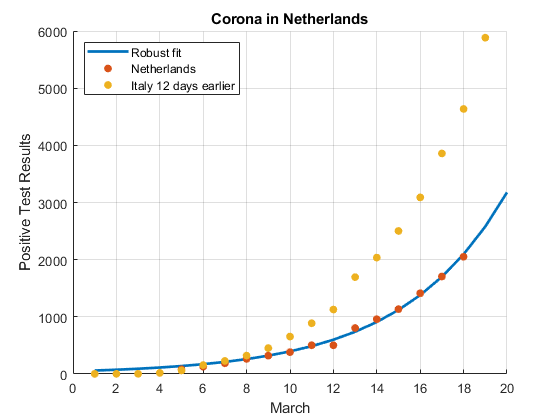

y_italy = getinfections('Italy','');

offset = 40; % this is march 1
timeshift = 12; % delay time series by 12 days
until_date = 40-timeshift+max(t); % plot until current date

y_italy_plot = y_italy((offset-timeshift):until_date);

figure;
hold on;
plot(tfar(:,1),feval(fitresult,tfar(:,1)),'DisplayName','Robust fit','LineWidth',linewidth)
plot(t,y,'.','MarkerSize',markersize,'DisplayName',country);
plot(y_italy_plot,'.','MarkerSize',markersize,'DisplayName',sprintf('Italy %d days earlier',timeshift));

grid on
title(sprintf('Corona in %s',country))
xlabel('March')
ylabel('Positive Test Results')
legend('Location','NorthWest');